# **Finding wave paremters (Hs, Tp...)**

clc
close all
clear all
%warning off

- Put in the timestack folder all the images for the period you want to analyze (Ideally, at least one week)


%addpath('./Timestacks/Timestacks_15min/');

> In path (line 109)
In addpath (line 86)
In addpath (line 49)
In <a

 addpath(genpath('./'))
path = 'C:\Users\Rafael\MATLAB Drive\Senegal\Timestacks\Timestacks_15min/'; % Output Figures and matlab files are saved here
f = '/MATLAB Drive/Senegal/Timestacks/Timestacks_15min/';
Img = dir([path,strcat('**/S_3_*')]);

- Reading camera parameters

load('rect_Jennifer.mat');
% dxXX = 1:4300; % This is temporary while we can the rectification vector 
dt = 1/3;                           % delta time. Sample Frequenzy at St Louis = 3 Hz.
H_camera         =  18.8;           % Camera height [m]
sk1              =  [2500 1];       % St Louis chosen transect
sk2              =  [1250 4300];
CoordCam         =  [0,0,H_camera]; 
BeachAng         = 3;

- Computing  wave parameters parameters

% duration = [3 5 10 15]; % This is the duration of the timestack in min. However, it's NOT necesary to try different. We just want to check the script is stable.
dur = 5;
colors = {'r', 'm', 'c','k'};

% Daily vectors after averaging the different timestacks for 1 day

Hs = [];
Hm = [];
T_p = [];
T_m = [];
t = [];
depthT=[];
CT=[];
for j = 1:length(Img)
    Img(j).name
    t = [t; datenum(Img(j).name(5:end-4),'yyyymmddHHMM')];
    [C,depth,hs,hm,Tm,Tp,Er,rolL,nbwave,Breakstd,Breakmean1,Breakmean2]=GPP_get_wave_parameters_20210827(Img(j).name,dt,CoordCam,dxXX./100,dur);
    Hs = [Hs; hs];
    Hm = [Hm; hm];
    T_p = [T_p; Tp];
    T_m = [T_m; Tm];
    depthT = [depthT; depth];
    CT = [CT; C];
    clear hs hm Tp Tm depth C
end

ans = 'S_3_202108011000.jpg'

Depth (Breakpoint) = 198967.24 m, at X = 13195.00 m


ans = 'S_3_202108011016.jpg'

Depth (Breakpoint) = 198967.24 m, at X = 14622.00 m


ans = 'S_3_202108011032.jpg'

Depth (Breakpoint) = 1802413.33 m, at X = 14598.00 m


ans = 'S_3_202108021000.jpg'

Depth (Breakpoint) = 1680160.68 m, at X = 123853.00 m


ans = 'S_3_202108021016.jpg'

Depth (Breakpoint) = 60850.85 m, at X = 26530.00 m


ans = 'S_3_202108021032.jpg'

Depth (Breakpoint) = 70970.94 m, at X = 26623.00 m


ans = 'S_3_202108031000.jpg'

Depth (Breakpoint) = 83725.88 m, at X = 27596.00 m


ans = 'S_3_202108031016.jpg'

Depth (Breakpoint) = 191515.41 m, at X = 16523.00 m


ans = 'S_3_202108031031.jpg'

Depth (Breakpoint) = 111279.96 m, at X = 12993.00 m


ans = 'S_3_202108041000.jpg'

Depth (Breakpoint) = 121666.56 m, at X = 24585.00 m


ans = 'S_3_202108041015.jpg'

Depth (Breakpoint) = 1377264.21 m, at X = 18886.00 m


ans = 'S_3_202108041031.jpg'

Depth (Breakpoint) = 1377264.21 m, at X = 18521.00 m


ans = 'S_3_202108051000.jpg'

Depth (Breakpoint) = 850534.60 m, at X = 37230.00 m


ans = 'S_3_202108051015.jpg'

Depth (Breakpoint) = 850534.60 m, at X = 41985.00 m


ans = 'S_3_202108051031.jpg'

Depth (Breakpoint) = 850534.60 m, at X = 40972.00 m


ans = 'S_3_202108061000.jpg'

Depth (Breakpoint) = 3101995.51 m, at X = 23177.00 m


ans = 'S_3_202108061015.jpg'

Depth (Breakpoint) = 1014242.70 m, at X = 46635.00 m


ans = 'S_3_202108061031.jpg'

Depth (Breakpoint) = 567253.61 m, at X = 47471.00 m


ans = 'S_3_202108071000.jpg'

Depth (Breakpoint) = 1014242.70 m, at X = 47162.00 m


ans = 'S_3_202108071015.jpg'

Depth (Breakpoint) = 589325.34 m, at X = 42600.00 m


ans = 'S_3_202108071031.jpg'

Depth (Breakpoint) = 589325.34 m, at X = 43429.00 m


ans = 'S_3_202108081000.jpg'

Depth (Breakpoint) = 431825.24 m, at X = 41375.00 m


ans = 'S_3_202108081016.jpg'

Depth (Breakpoint) = 431825.24 m, at X = 40732.00 m


ans = 'S_3_202108081031.jpg'

Depth (Breakpoint) = 431825.24 m, at X = 40492.00 m


ans = 'S_3_202108091000.jpg'

Depth (Breakpoint) = 287156.36 m, at X = 13741.00 m


ans = 'S_3_202108091018.jpg'

Depth (Breakpoint) = 287156.36 m, at X = 14575.00 m


ans = 'S_3_202108091034.jpg'

Depth (Breakpoint) = 1377264.21 m, at X = 19946.00 m


ans = 'S_3_202108101000.jpg'

Depth (Breakpoint) = 1377264.21 m, at X = 21699.00 m


ans = 'S_3_202108101015.jpg'

Depth (Breakpoint) = 850534.60 m, at X = 36479.00 m


ans = 'S_3_202108101031.jpg'

Depth (Breakpoint) = 4976504.11 m, at X = 265868.00 m



size(CT)

ans =           30        4300


size(depthT)

ans =           30        4300



disp(num2str(length(Img)))

30


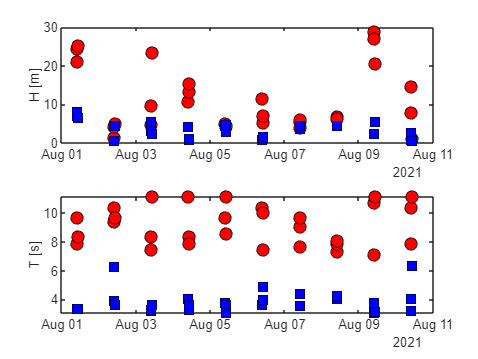

Time = datetime(t(:),'ConvertFrom','datenum');
WP = timetable(Time, Hs, Hm, T_p, T_m);
WP_daily = retime(WP, 'daily', 'mean');

figure(1)
subplot(211)
plot(WP.Time,WP.Hs,'ok','MarkerSize',8,'MarkerFaceColor','r')
hold on
plot(WP.Time,WP.Hm,'sk','MarkerSize',8,'MarkerFaceColor','b')
ylabel('H [m]')

subplot(212)
plot(WP.Time,WP.T_p,'ok','MarkerSize',8,'MarkerFaceColor','r')
hold on
plot(WP.Time,WP.T_m,'sk','MarkerSize',8,'MarkerFaceColor','b')
ylabel('T [s]')

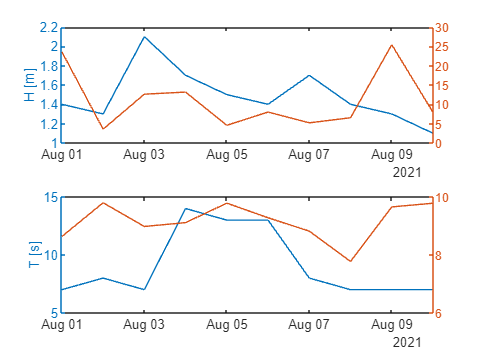


Hs_m = [1.4 1.3 2.1 1.7 1.5 1.4 1.7 1.4 1.3 1.1];
Tp_m = [7 8 7 14 13 13 8 7 7 7];

figure(2)
subplot(211)
plotyy(WP_daily.Time,Hs_m,WP_daily.Time,WP_daily.Hs)
ylabel('H [m]')

subplot(212)
plotyy(WP_daily.Time,Tp_m,WP_daily.Time,WP_daily.T_p)
ylabel('T [s]')

saveas(gcf,strcat(out_path,'Comparison',Img(1).name(5:end-4),'_',Img(end).name(5:end-4),'.jpg'))

Error using saveas (line 138)
Invalid or missing path: ./Output/Comparison202108011000_202108101031.jpg


save(strcat(out_path,'WP_',Img(j).name(5:end-4)),'WP', 'WP_daily')
%     saveas(gcf,strcat(out_path,Img(1).name(5:end-4),'_',Img(end).name(5:end-4),'.jpg'))
%     saveas(gcf,strcat(out_path,Img(1).name(5:end-4),'_',Img(end).name(5:end-4),'.fig'))
% WindGuru Data for Dakar-Senegal (For Aug, 1-10)


